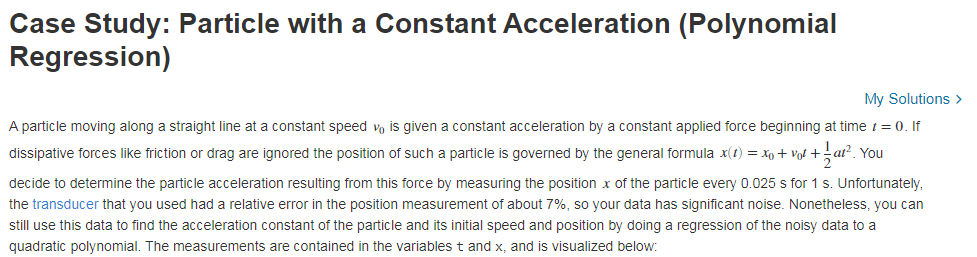

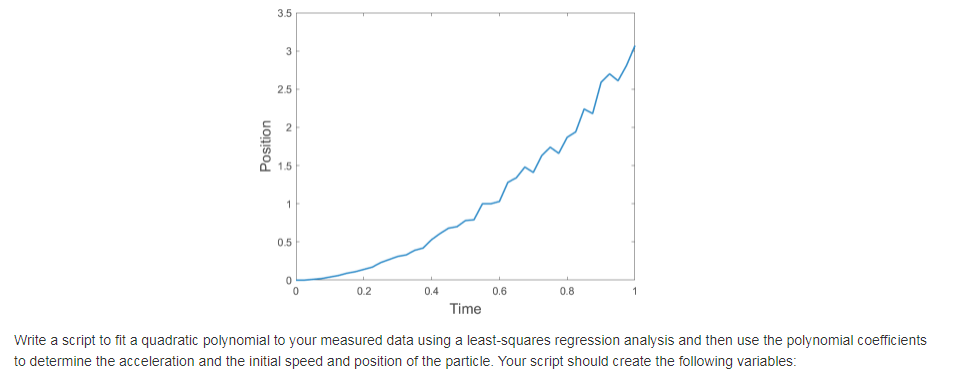

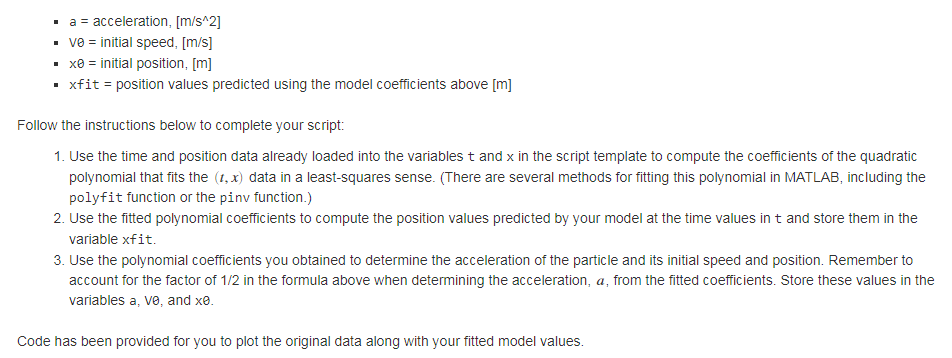

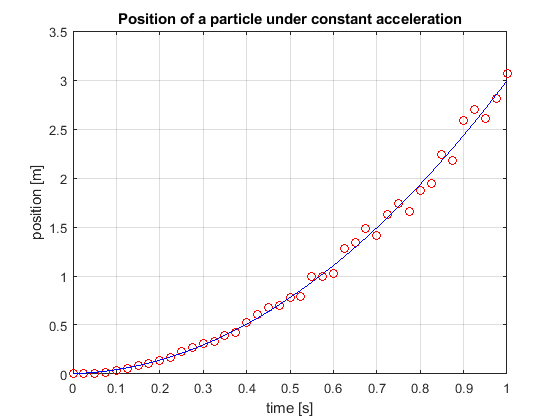

x   =  [0 0 0.0100 0.0200 0.0400 0.0600 0.0900 0.1100  0.1400 0.1700 0.2300 0.2700 0.3100 0.3300 0.3900 0.4200 0.5300 0.6100 0.6800 0.7000 0.7800 0.7900 1.0000 1.0000 1.0300 1.2800 1.3400 1.4800 1.4100 1.6300 1.7400 1.6600 1.8700 1.9400 2.2400 2.1800 2.5900 2.7000 2.6100 2.8100 3.0700];
t = [0 0.0250 0.0500 0.0750 0.1000 0.1250 0.1500 0.1750 0.2000 0.2250 0.2500 0.2750 0.3000 0.3250 0.3500 0.3750 0.4000 0.4250 0.4500 0.4750 0.5000 0.5250 0.5500 0.5750 0.6000 0.6250 0.6500 0.6750 0.7000 0.7250 0.7500 0.7750 0.8000 0.8250 0.8500 0.8750 0.9000 0.9250 0.9500 0.9750 1.0000];

% Fit the data with a regression to a quadratic polynomial.
p=polyfit(t,x,2);

% Compute the fitted model values.
xfit  = p(1).*t.^2+p(2).*t+p(3);

% Obtain the physical model coefficients.
a = 2*p(1);

v0 = 2*p(1).*t(1)+p(2);

x0 = p(1).*t(1).^2+p(2).*t(1)+p(3);


%%%%%%%%%%%%% Plotting Code Below %%%%%%%%%%%%%%%
% Plot the results.
plot(t,x,'ro', t,xfit,'b');
xlabel('time [s]');
ylabel('position [m]');
title('Position of a particle under constant acceleration');
grid;


% Print the results.
fprintf('.\n');

.


fprintf(' a = %5.3f [m/s^2]\n',a); 

 a = 5.756 [m/s^2]


fprintf('v0 = %5.3f [m/s]\n',v0); 

v0 = 0.111 [m/s]


fprintf('x0 = %.3e [m]\n',x0); 

x0 = 4.069e-03 [m]
